% Set up
clc;
close all;
clear;

## **Load and **Re-organize data (EEG)

The data is set to m*n matrix

m = number of epochs

n = Frequency of Sampling * epoch length

% Initialize variables to store overall results
all_test_predictions = {};
all_test_labels = {};
all_test_indices = [];
overall_accuracies = zeros(1, 10);
per_subject_results = cell(1, 10);

% Main leave-one-out loop
for test = 1:1
    fprintf('\n=== Processing patient %d as test subject ===\n', test);
    
    EEG1 = [];
    EEG2 = [];
    STAGE = [];
    
    % load test data
    edfFilename = sprintf('R%d_edf.mat', test);
    xmlFilename = sprintf('R%d_xml.mat', test);
    load(edfFilename);
    load(xmlFilename);
    
    % We can know from the hdr that the 3rd and the 8th 
    % channel of the record is EEG signal
    Fs = hdr.samples(3);
    % every epoch lasts for epochLength seconds (30 seconds)
    numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
    % Initialization of eeg1 and eeg2
    eeg1 = zeros(numberOfEpochs,Fs*epochLength);
    eeg2 = zeros(numberOfEpochs,Fs*epochLength);
    epochAmount = 1;    % How much epoches to cut for one row
    for i = 1:numberOfEpochs
        epochNumber = i;    % start epoch No.
        epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
        epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
        t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
        eeg1(i,:) = record(8,epochStart:epochEnd);
        eeg2(i,:) = record(3,epochStart:epochEnd);
    end
    EEG1_test = eeg1;
    EEG2_test = eeg2;
    % process the stages
    stages_epoch = zeros(1,numberOfEpochs);
    for i = 1:numberOfEpochs
        stages_epoch(i) = stages(i*30);
    end
    STAGE_test = stages_epoch;

    train = 1:10;
    train(train == test) = [];
    % load train data
    for n = train
        edfFilename = sprintf('R%d_edf.mat', n);
        xmlFilename = sprintf('R%d_xml.mat', n);
        load(edfFilename);
        load(xmlFilename);

        % every epoch lasts for epochLength seconds (30 seconds)
        numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
        % Initialization of eeg1 and eeg2
        eeg1 = zeros(numberOfEpochs,Fs*epochLength);
        eeg2 = zeros(numberOfEpochs,Fs*epochLength);
        epochAmount = 1;    % How much epoches to cut for one row
        for i = 1:numberOfEpochs
            epochNumber = i;    % start epoch No.
            epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
            epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
            t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
            eeg1(i,:) = record(8,epochStart:epochEnd);
            eeg2(i,:) = record(3,epochStart:epochEnd);
        end
        EEG1 = [EEG1;eeg1];
        EEG2 = [EEG2;eeg2];
        % process the stages
        stages_epoch = zeros(1,numberOfEpochs);
        for i = 1:numberOfEpochs
            stages_epoch(i) = stages(i*30);
        end
        STAGE = [STAGE,stages_epoch];
    end

%     % Plot the first epoch
%     figure(1)
%     subplot(2,1,1)
%     plot(t,EEG1(1,:))
%     subplot(2,1,2)
%     plot(t,EEG2(1,:))

## Remove the baseline drift

    % It will filter every row
    EEG1_filtered = baseline_drift_removal(EEG1,Fs,0.5);
    EEG2_filtered = baseline_drift_removal(EEG2,Fs,0.5);

    EEG1_test_filtered = baseline_drift_removal(EEG1_test,Fs,0.5);
    EEG2_test_filtered = baseline_drift_removal(EEG2_test,Fs,0.5);

## Muscle noise filtering & Power line interference removal

    EEG1_filtered = muscle_noise_filtering(EEG1_filtered,Fs,30);
    EEG2_filtered = muscle_noise_filtering(EEG2_filtered,Fs,30);

    EEG1_test_filtered = muscle_noise_filtering(EEG1_test_filtered,Fs,30);
    EEG2_test_filtered = muscle_noise_filtering(EEG2_test_filtered,Fs,30);
    

## Feature Extraction - Time-domain

    features_time_eeg1 = extract_time_features(EEG1_filtered);
    features_time_eeg2 = extract_time_features(EEG2_filtered);
    
    features_time_eeg1_test = extract_time_features(EEG1_test_filtered);
    features_time_eeg2_test = extract_time_features(EEG2_test_filtered);
    
    feature_labels = {'Mean', 'Variance', 'Skewness', 'Kurtosis', ...
                      'Zero-Crossing Rate', 'Hjorth Activity', ...
                      'Hjorth Mobility', 'Hjorth Complexity'};
    
    disp('Characteristics of EEG1 (Time-Domain):');
    for i = 1:length(feature_labels)
        fprintf('%s: %.4f\n', feature_labels{i}, features_time_eeg1(i));
    end

    disp('Characteristics of EEG2 (Time-Domain):');
    for i = 1:length(feature_labels)
        fprintf('%s: %.4f\n', feature_labels{i}, features_time_eeg2(i));
    end

## Feature Extraction - Frequency Domain

    [features_freq_eeg1, Pxx_eeg1, freqs_eeg1] = extract_freq_features(EEG1_filtered, Fs);
    [features_freq_eeg2, Pxx_eeg2, freqs_eeg2] = extract_freq_features(EEG2_filtered, Fs);
    
    [features_freq_eeg1_test, Pxx_eeg1_test, freqs_eeg1_test] = extract_freq_features(EEG1_test_filtered, Fs);
    [features_freq_eeg2_test, Pxx_eeg2_test, freqs_eeg2_test] = extract_freq_features(EEG2_test_filtered, Fs);
    
    feature_labels_freq = {'Power Delta', 'Power Theta', 'Power Alpha', 'Power Beta', 'Power Gamma', ...
                          'Spectral Edge Frequency', ...
                          'Relative Delta', 'Relative Theta', 'Relative Alpha', 'Relative Beta', 'Relative Gamma'};
    
    disp('Characteristics of EEG1 (Frequency-Domain):');
    for i = 1:length(feature_labels_freq)
        fprintf('%s: %.4f\n', feature_labels_freq{i}, features_freq_eeg1(i));
    end
    
    disp('Characteristics of EEG2 (Frequency-Domain):');
    for i = 1:length(feature_labels_freq)
        fprintf('%s: %.4f\n', feature_labels_freq{i}, features_freq_eeg2(i));
    end
    
%     figure;
%     subplot(2,1,1);
%     plot(freqs_eeg1, Pxx_eeg1(1,:));
%     xlabel('Frequency (Hz)');
%     ylabel('Power');
%     title('EEG1 Power Spectrum');
%     xlim([0 40]);
%     
%     subplot(2,1,2);
%     plot(freqs_eeg2, Pxx_eeg2(1,:));
%     xlabel('Frequency (Hz)');
%     ylabel('Power');
%     title('EEG2 Power Spectrum');
%     xlim([0 40]);
    
    

## Time Frequency

    % Extract time-frequency features
    features_timefreq_eeg1 = extract_timefreq_features(EEG1_filtered, Fs);
    features_timefreq_eeg2 = extract_timefreq_features(EEG2_filtered, Fs);
    
    features_timefreq_eeg1_test = extract_timefreq_features(EEG1_test_filtered, Fs);
    features_timefreq_eeg2_test = extract_timefreq_features(EEG2_test_filtered, Fs);
    
    % Append the new features to the existing feature set
    features = [features_time_eeg1, features_freq_eeg1, features_timefreq_eeg1];
    features_test = [features_time_eeg1_test, features_freq_eeg1_test, features_timefreq_eeg1_test];
    
%     % Display extracted features
%     disp('Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):');
%     disp(features_timefreq_eeg1);  
%     
%     disp('Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):');
%     disp(features_timefreq_eeg2);  
%     
%     disp('Time-Frequency Features for EEG1 (Test Data):');
%     disp(features_timefreq_eeg1_test);  
%     
%     disp('Time-Frequency Features for EEG2 (Test Data):');
%     disp(features_timefreq_eeg2_test);  
%     
%     % Plot extracted features for EEG1
%     figure;
%     
%     subplot(2,1,1);
%     plot(features_timefreq_eeg1(:,1), 'b', 'LineWidth', 1.5); 
%     title('Wavelet Energy - EEG1');
%     ylabel('Energy');
%     xlabel('Epoch');
%     grid on;
%     
%     subplot(2,1,2);
%     plot(features_timefreq_eeg1(:,2), 'r', 'LineWidth', 1.5); 
%     title('Spectral Entropy - EEG1');
%     ylabel('Entropy');
%     xlabel('Epoch');
%     grid on;
%     
%     set(gcf, 'color', 'w'); % Set background color to white
%     
%     % Plot extracted features for EEG2
%     figure;
%     
%     subplot(2,1,1);
%     plot(features_timefreq_eeg2(:,1), 'b', 'LineWidth', 1.5); 
%     title('Wavelet Energy - EEG2');
%     ylabel('Energy');
%     xlabel('Epoch');
%     grid on;
%     
%     subplot(2,1,2);
%     plot(features_timefreq_eeg2(:,2), 'r', 'LineWidth', 1.5); 
%     title('Spectral Entropy - EEG2');
%     ylabel('Entropy');
%     xlabel('Epoch');
%     grid on;
%     
%     set(gcf, 'color', 'w'); % Set background color to white

## Classification


=== Processing patient 1 as test subject ===


Characteristics of EEG1 (Time-Domain):


Mean: 0.0210
Variance: 0.1810
Skewness: -0.2066
Kurtosis: 0.0449
Zero-Crossing Rate: -0.0313
Hjorth Activity: -0.0355
Hjorth Mobility: 0.0293
Hjorth Complexity: -0.1628


Characteristics of EEG2 (Time-Domain):


Mean: 0.0262
Variance: 0.0159
Skewness: -0.0881
Kurtosis: -0.0394
Zero-Crossing Rate: -0.2019
Hjorth Activity: -0.0408
Hjorth Mobility: 0.0099
Hjorth Complexity: -0.1252


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 6777.4693
Power Theta: 11229.3600
Power Alpha: 6513.6253
Power Beta: 9211.2052
Power Gamma: 11123.9064
Spectral Edge Frequency: 9768.1778
Relative Delta: 11233.6962
Relative Theta: 5817.6840
Relative Alpha: 9474.2615
Relative Beta: 3117.6757
Relative Gamma: 5575.2584


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 6800.7709
Power Theta: 11995.7519
Power Alpha: 9237.0458
Power Beta: 9757.0650
Power Gamma: 10851.7076
Spectral Edge Frequency: 6514.8886
Relative Delta: 13328.4631
Relative Theta: 4860.2425
Relative Alpha: 10289.2710
Relative Beta: 4212.5765
Relative Gamma: 4973.0364


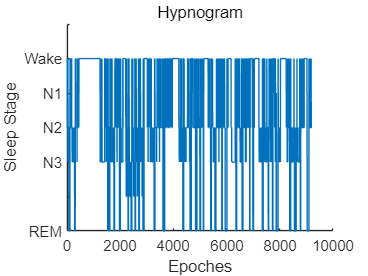

错误使用 array2table
对于表中的每个变量，VariableNames 属性必须包含一个名称。

出错 trainClassifier3 (第 4 行)
inputTable = array2table(trainingData, 'VariableNames', {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6', 'column_7', 'column_8', 'column_9', 'column_10', 'column_11', 'column_12', 'column_13', 'column_14', 'column_15', 'column_16', 'column_17', 'column_18', 'column_19'});

%     features = [features_time_eeg1, features_freq_eeg1];
    features = normalize(features);
    labels = categorical(STAGE, [0 1 2 3 4 5], {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'});
        
%     features_test = [features_time_eeg1_test, features_freq_eeg1_test];
    features_test = normalize(features_test);
    labels_test = categorical(STAGE_test, [0 1 2 3 4 5], {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'});
    
    figure;
    plot(STAGE); %sleep stages are for 30 seconds epochs
    ylim([0 6]);
    set(gca,'ytick',0:6,'yticklabel',{'REM','','N3','N2','N1','Wake',''});
    xlabel('Epoches');
    ylabel('Sleep Stage');
    box off;
    title('Hypnogram');
    set(gcf,'color','w');
    
    % Train and test
    [trainedClassifier, validationAccuracy, f1Score, perStageAccuracy] = trainClassifier3(features, labels);
        
    % Store test results
    testPredictions = predict(trainedClassifier.ClassificationKNN, features_test);
    all_test_predictions{test} = testPredictions;
    all_test_labels{test} = labels_test;
    all_test_indices = [all_test_indices; test*ones(length(labels_test),1)];
        
    % Calculate and store accuracy for this test subject
    correct_predictions = sum(testPredictions == labels_test);
    total_predictions = length(labels_test);
    subject_accuracy = correct_predictions / total_predictions;
    overall_accuracies(test) = mean(subject_accuracy);
    overall_accuracies(test) = subject_accuracy(1); 
        
    % Store per-subject results
    per_subject_results{test} = struct(...
        'predictions', testPredictions, ...
        'labels', labels_test, ...
        'accuracy', subject_accuracy, ...
        'confusion', confusionmat(labels_test, testPredictions));
        
    % Plot confusion matrix for this subject
    figure;
    confusionchart(labels_test, testPredictions);
    title(sprintf('Confusion Matrix for Subject %d (Held-Out Test)', test));
end


%% Display overall results
fprintf('\n=== Leave-One-Out Cross-Validation Results ===\n');
fprintf('Individual Subject Accuracies:\n');
for i = 1:test
    fprintf('Subject %d: %.2f%%\n', i, overall_accuracies(i)*100);
end
fprintf('\nMean Accuracy: %.2f%%\n', mean(overall_accuracies)*100);
fprintf('Standard Deviation: %.2f%%\n', std(overall_accuracies)*100);


% Combine all predictions and labels for overall confusion matrix
categories = {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'};
all_predictions_combined = [];
all_labels_combined = [];

for i = 1:test
    % Convert to categorical if not already
    if ~iscategorical(all_test_predictions{i})
        current_pred = categorical(all_test_predictions{i}, 0:5, categories);
    else
        current_pred = all_test_predictions{i};
    end
    
    if ~iscategorical(all_test_labels{i})
        current_labels = categorical(all_test_labels{i}, 0:5, categories);
    else
        current_labels = all_test_labels{i};
    end
    
    % Ensure consistent categories
    current_pred = reordercats(current_pred, categories);
    current_labels = reordercats(current_labels, categories);
    
    all_predictions_combined = [all_predictions_combined; current_pred(:)];
    all_labels_combined = [all_labels_combined; current_labels(:)];
end

% Plot overall confusion matrix
figure;
confusionchart(all_labels_combined, all_predictions_combined);
title('Overall Confusion Matrix for Leave-One-Out Cross-Validation');